# Differential Drive Model

It's kinematic model is defined as:

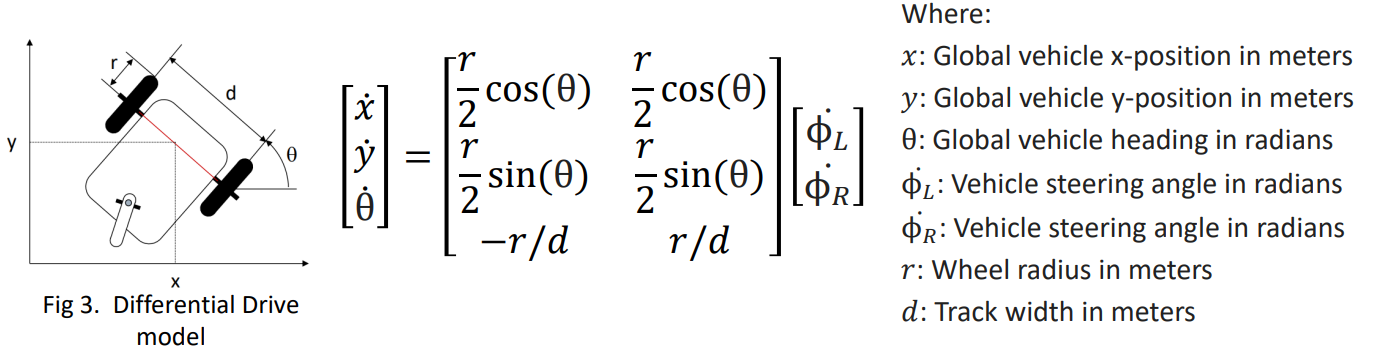

The equation of motion is similar to the Unicycle, with $v$ and $\omega$ depending on the veocities of each wheel: $\dot \phi_L$ and $\dot \phi_R
$

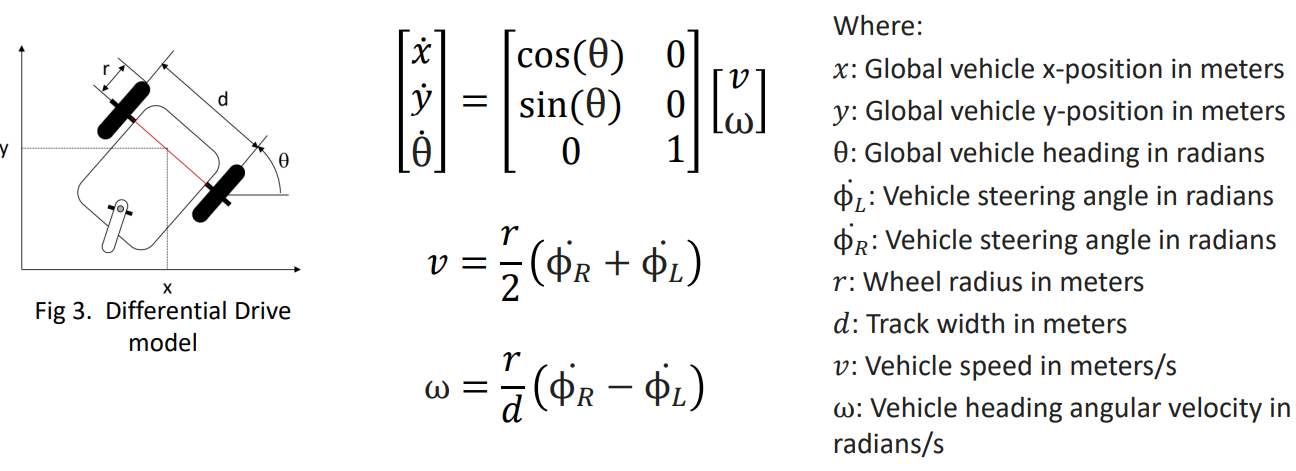  

## **Part 1: Custom Differential Drive Model**

IHere we define a function called `diffDrive ``that` implements a simplified differential drive kinematics model. The model computes the vehicle’s state (position x, y, and orientation θ) based on the following parameters:

- **Wheel Radius (**`r`**)**: 0.1 m.

- **Track Width (**`d`**)**: 0.5 m (distance between the wheels).

- **Wheel Speeds**:   Left wheel speed ($\dot \phi_L$): 10 rad/s; Right wheel speed ($\dot \phi_R
$): 0 rad/s.

- **Linear Velocity (**`v`**)**: Computed as $v = \frac{r}{2} (\dot \phi_R + \dot \phi_L)$

- **Angular Velocity (**$\omega$**)**: Computed as $\omega
 = \frac{r}{d} (\dot \phi_R - \dot \phi_L)$.

The `ode45` solver integrates the differential equations to generate the vehicle's trajectory, which is then plotted.

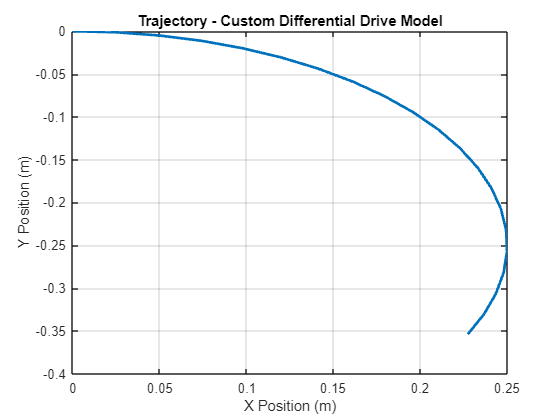

clc
clear
close all

% Custom Differential Drive Model
tspan = 0:0.05:1; 
initialState = [0 0 0];
[t, q] = ode45(@diffDrive, tspan, initialState);

figure
plot(q(:,1), q(:,2), 'LineWidth', 2)
title('Trajectory - Custom Differential Drive Model')
xlabel('X Position (m)')
ylabel('Y Position (m)')
grid on

## **Part 2: MATLAB's Built-In Differential Drive Kinematics**

In this section, MATLAB's built-in `differentialDriveKinematics` function is used:

- An instance of `differentialDriveKinematics` is created with the modes `"VehicleInputs"` and `"VehicleSpeedHeadingRate"`.

- The properties are set to: 

- **TrackWidth**: 0.5 m.

- **WheelRadius**: 0.1 m.

- The input vector `[0.5, -2]` is used to represent the vehicle speed and heading rate.

- A function handle is defined to compute the state derivatives using the model’s `derivative` method.

- The system is integrated with `ode45`, and the resulting trajectory is plotted.

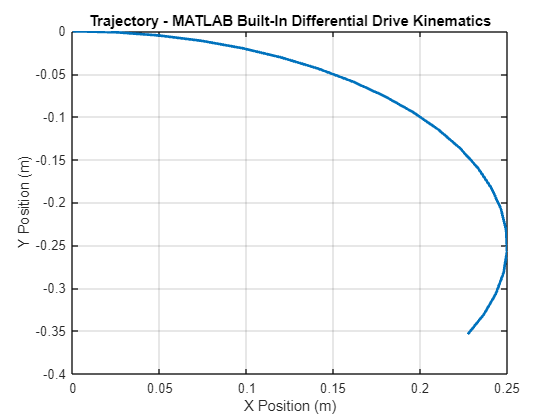

% Using Matlab differential Drive Kinematics
input = [0.5, -2];
diffDriveModel = differentialDriveKinematics("VehicleInputs", "VehicleSpeedHeadingRate");
diffDriveModel.TrackWidth = 0.5;
diffDriveModel.WheelRadius = 0.1;
[t, q_diffDrive] = ode45(@(t, q_diffDrive) derivative(diffDriveModel, q_diffDrive, input), tspan, initialState);

figure
plot(q_diffDrive(:,1), q_diffDrive(:,2), 'LineWidth', 2)
title('Trajectory - MATLAB Built-In Differential Drive Kinematics')
xlabel('X Position (m)')
ylabel('Y Position (m)')
grid on

% Custom Differential Drive Model Function

function dq = diffDrive(t, q)
    % Extract state variables
    x  = q(1);
    y  = q(2);
    th = q(3);

    % Model parameters
    r = 0.1;  % Wheel radius [m]
    d = 0.5;  % Track width (distance between wheels) (m)

    % Wheel speeds (rad/s)
    dph_L = 10;   % Left wheel speed (rad/s)
    dph_R = 0;  % Right wheel speed (rad/s)

    % Compute linear and angular velocities
    v = (r/2) * (dph_R + dph_L);  % Linear velocity (m/s)
    w = (r/d) * (dph_R - dph_L);   % Angular velocity (rad/s)

    % Compute state derivatives
    dq = [cos(th) 0;
          sin(th) 0;
          0       1] * [v; w];
end

Both approaches allow us to compare the behavior of the custom differential drive model with MATLABBs built-in functionality.